%Levent Batakci
%3/28/2021
%Math444 Midterm Project

%Load the data
load cities.mat

%Format the data
ratings = ratings';
[n, p] = size(ratings);
%ratings = ratings ./ sum(ratings,2);


%Extract the categories
categories = string(categories)';

%Get the states
states = char(p, 10);
for i = 1:p
    name = names(i,:);
    nonEmpty = find(name ~= ' ');
    stopChar = nonEmpty(end);
    while stopChar > 0 && name(stopChar) ~= ' '
        stopChar = stopChar-1;
    end
    states(i,1:nonEmpty(end)-stopChar) = name(stopChar+1:nonEmpty(end));
end

## DATA REFORMATING

%This section manipulates the data so that individual scores are more
%representative of how well a city does in an area as compared to other
%cities

relativeRatings = zeros(size(ratings));
for c = 1:n
    [~, I] = sort(ratings(c,:));
    for i = 1:p
        relativeRatings(c,I(i)) = i;
    end
end
relativeRatings = relativeRatings - sum(relativeRatings,2)/p;

## Principal Component Analysis

[Z, Ur] = PCA_r(ratings, 2); %Compute the PCA

%First two feature vectors
u1 = Ur(:,1);
u2 = Ur(:,2);

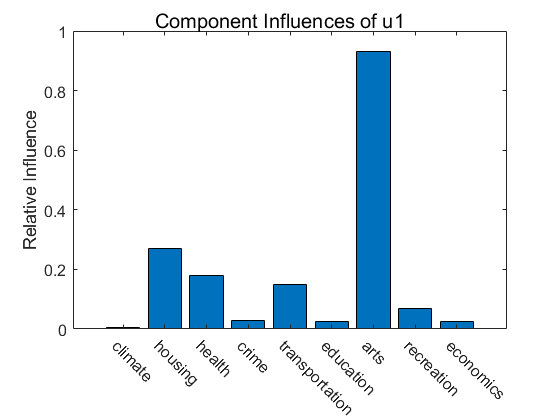

%Compare the impact of attributes on the feature vectors
figure(1)
bar(abs(u1))%Bar graph of u1's absolute components
ylabel("Relative Influence", "FontSize",15)
set(gca,'xticklabel',categories, 'FontSize', 12)
xtickangle(-45)
sgtitle("Component Influences of u1", "Fontsize", 15)

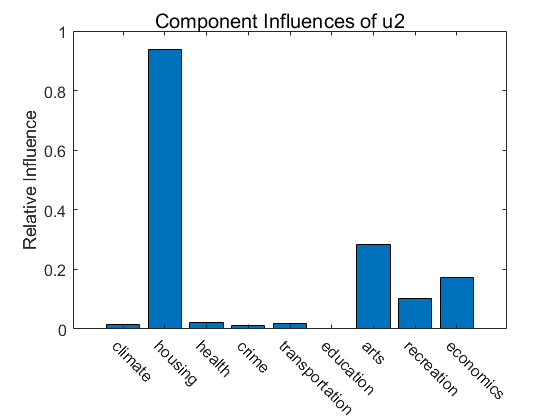


figure(2)
bar(abs(u2)) %Bar graph of u2's absolute components
ylabel("Relative Influence", "FontSize",15)
set(gca,'xticklabel',categories, 'FontSize', 12)
xtickangle(-45)
sgtitle("Component Influences of u2", "Fontsize", 15)

## K-Medoids

D = dMatrix(ratings, @norm2);
K=[3 4 5];
tau = 0.5;

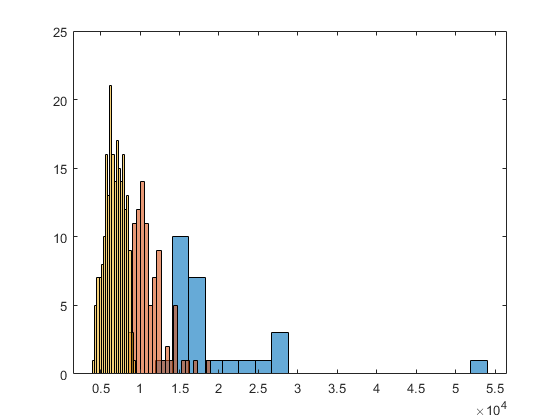

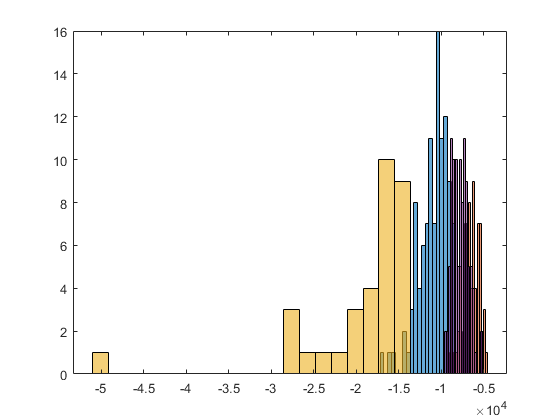

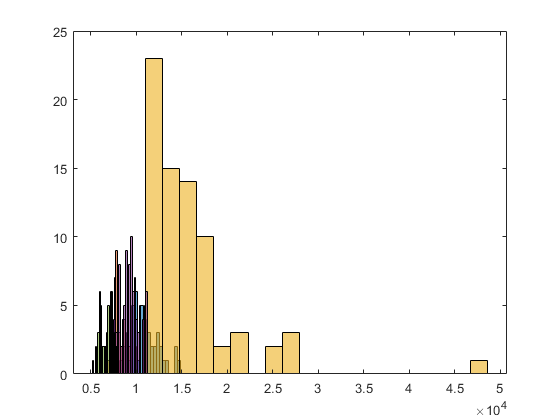

%Compute the labeling
colors = ['r','b','g', 'k', 'purple'];
I = zeros(size(K,2), size(ratings,2));
for i = 1:size(K,2)
    k = K(i);
    I = kMedoids_distMatrix(k, D, tau, 10);
    [~,Z_] = LDA(ratings, I);
    figure(2+i)
    for label = 1:k
        Z1 = Z_(1, I==label);
        histogram(Z1, 20, 'LineWidth',0.01);
        hold on
    end
    hold off
end

% D = dMatrix(relativeRatings, @norm2);
% colors = ['r','b','g', 'k', 'purple'];
% I = zeros(size(K,2), size(ratings,2));
% for i = 1:size(K,2)
%     k = K(i);
%     I = kMedoids_distMatrix(k, D, tau, 10);
%     [~,Z_] = LDA(ratings, I);
%     figure(2+i)
%     for label = 1:k
%         Z1 = Z_(1, I==label);
%         Z2 = Z_(2, I==label);
%         scatter(Z1, Z2, colors(label));
%         hold on
%     end
%     hold off
% end

## Non-negative Matrix Factorization

r=5;
[W, H] = NMF(ratings, r, 0.001);
disp("W: ")

W: 


disp([categories' W/1000])

    "climate       "    "0.23782"      "0.24073"     "0.12328"    "0.24278"       "0.054304"
    "housing       "    "6.6115"       "2.8125"      "0.14537"    "3.5746"        "1.7178"  
    "health        "    "0.33079"      "0.4411"      "0.18492"    "0.16027"       "1.4279"  
    "crime         "    "0.0072117"    "0.37687"     "0.55888"    "0.49826"       "0.213"   
    "transportation"    "0.64935"      "3.3905"      "2.5762"     "0.15794"       "0.67838" 
    "education     "    "0.51739"      "1.5837"      "0.82334"    "1.3572"        "0.29849" 
    "arts          "    "0.38308"      "0.01272"     "0.33653"    "0.00073435"    "7.6052"  
    "recreation    "    "0.76625"      "0.030091"    "1.8787"     "0.6618"        "0.14317" 
    "economics     "    "0.35428"      "2.5676"      "1.611"      "3.9027"        "0.43578" 



Ratings_Approx = W*H;

norm(ratings - Ratings_Approx,"fro") / norm(ratings,'fro')

ans = 0.0579

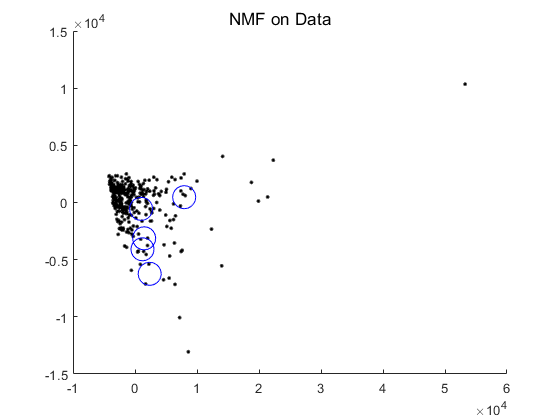


Zapprox = Ur' * W;

figure(3 + size(K,2))
scatter(Z(1,:), Z(2,:), 50, 'k.');
hold on
scatter(Zapprox(1,:), Zapprox(2,:), 300, 'bo');
sgtitle("NMF on Data")
hold off

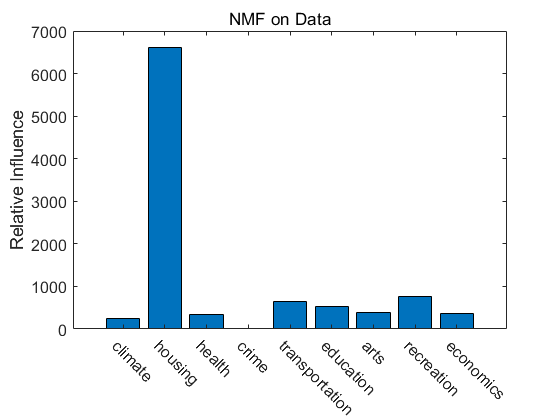

bar(W(:,1))
ylabel("Relative Influence", "FontSize",15)
set(gca,'xticklabel',categories, 'FontSize', 12)
xtickangle(-45)

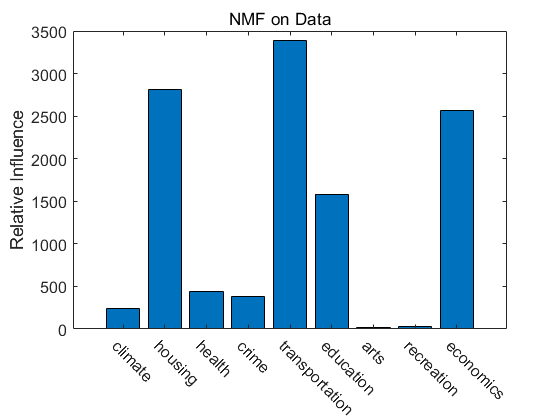

bar(W(:,2))
ylabel("Relative Influence", "FontSize",15)
set(gca,'xticklabel',categories, 'FontSize', 12)
xtickangle(-45)

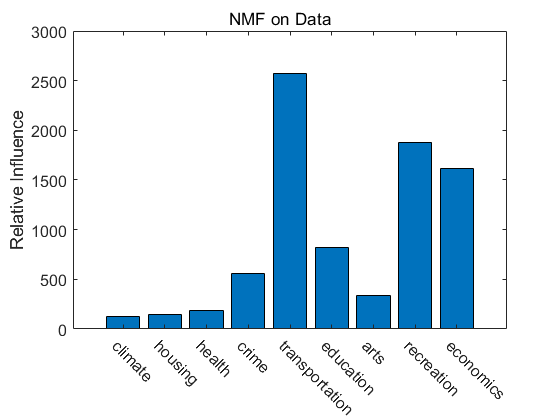

bar(W(:,3))
ylabel("Relative Influence", "FontSize",15)
set(gca,'xticklabel',categories, 'FontSize', 12)
xtickangle(-45)

%TRY WITH REFORMATTED DATA
% r=3;
% [W, H] = NMF(relativeRatings, r, 0.001);
% disp("W: ")
% disp([categories' W])
% approx = W*H;
% 
% norm(relativeRatings - approx,"fro") / norm(ratings,'fro')
% 
% [relativeU,~,~] = svd(relativeRatings);
% relativeUr = relativeU(:,1:r);
% Zapprox = relativeUr' * W;
% 
% relativeZ = relativeUr' * relativeRatings;
% 
% figure(8 + size(K,2))
% scatter(relativeZ(2,:), relativeZ(3,:), 50, 'k.');
% hold on
% scatter(Zapprox(2,:), Zapprox(3,:), 300, 'bo');
% sgtitle("NMF on Relative Data")
% hold off

% %First two feature vectors
% u1 = relativeUr(:,2);
% u2 = relativeUr(:,3);
% 
% %Compare the impact of attributes on the feature vectors
% figure(1)
% bar(abs(u1))%Bar graph of u1's absolute components
% ylabel("Relative Influence", "FontSize",15)
% set(gca,'xticklabel',categories, 'FontSize', 12)
% xtickangle(-45)
% sgtitle("Component Influences of u1", "Fontsize", 15)
% 
% figure(2)
% bar(abs(u2)) %Bar graph of u2's absolute components
% ylabel("Relative Influence", "FontSize",15)
% set(gca,'xticklabel',categories, 'FontSize', 12)
% xtickangle(-45)
% sgtitle("Component Influences of u2", "Fontsize", 15)

## Category Percentiles

% %Compute the average of all their scores for each city
% averageRating = sum(ratings,1) / n;
% max_rating = max(averageRating);
% 
% last = 0;
% %Compute the percentiles (in 1% increments)
% sortedAverages = sort(averageRating);
% percentile = zeros(100,1);
% for i = 1:p
%     percent = ceil(i * 100 / p);
%     percentile(percent) = sortedAverages(i);
% end
% 
% figure(4 + size(K,2))
% plot( percentile, 1:100);
% sgtitle("Average Score Percentile Distribution")
% xlabel("Rating")
% ylabel("Percentile")

% %Category-wise ranking
% figure(5 + size(K,2))
% for c = 1:n
%         %Compute the percentiles (in 1% increments)
%     sortedRatings = sort(ratings(c,:));
%     percentile = zeros(100,1);
%     for i = 1:p
%         percent = ceil(i * 100 / p);
%         percentile(percent) = sortedRatings(i);
%     end
%     
%     plot(percentile, 1:100);
%     hold on
% end
% legend(categories)
% sgtitle("Categories and Percentile Distribution")
% xlabel("Rating")
% ylabel("Percentile")

## SOM

%Define parameters
k = 100;
N = k^(1/2);
params = defaultParams(k, 2);

%Compute the SOM
ratings_scaled = ratings ./ sum(ratings,2);
M = SOM(relativeRatings, k, params);

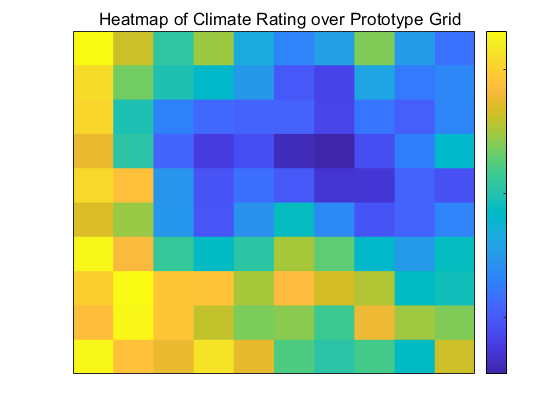

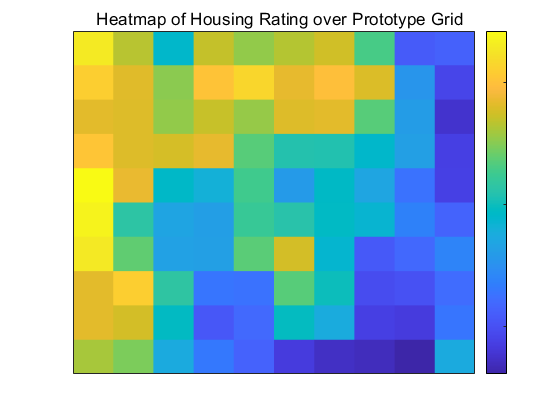

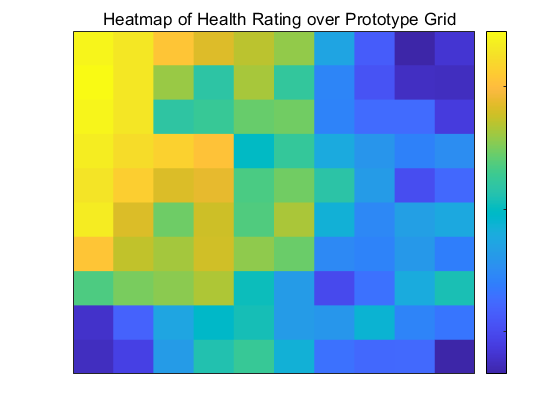

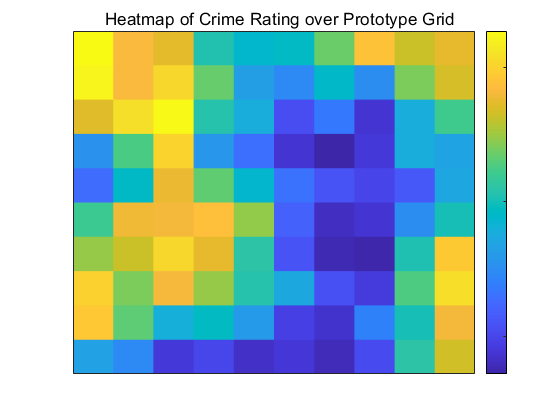

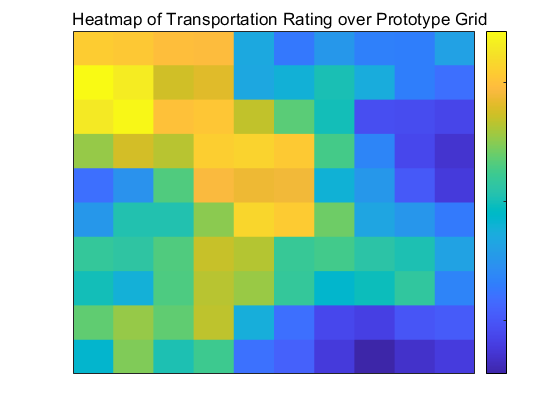

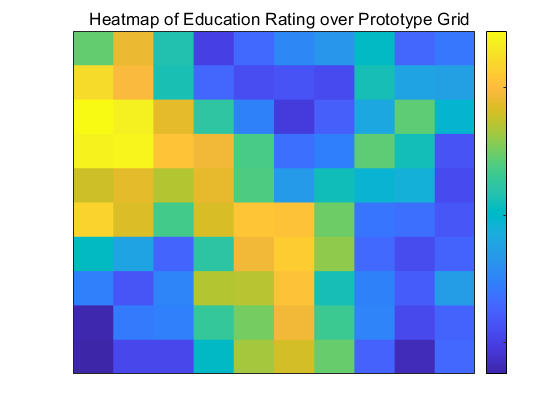

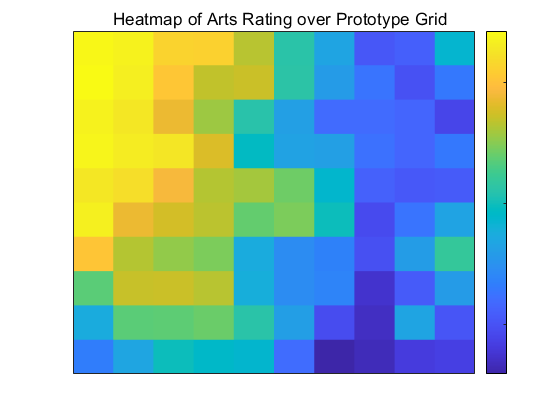

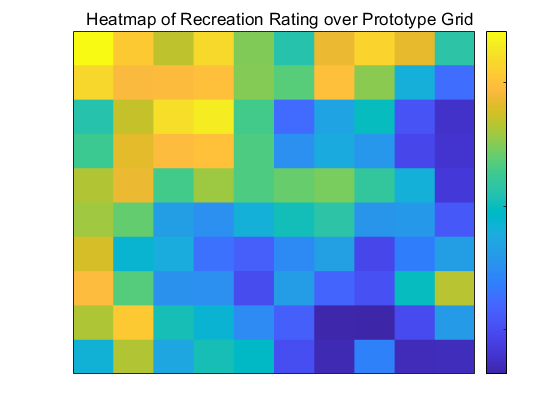

%Lets look at some heatmaps to understand the grid better
cats = ["Climate", "Housing", "Health", "Crime", "Transportation", "Education", "Arts", "Recreation", "Economics"];

for cat = 1:n
    C = zeros(N,N);

    for i = 1:k
        c = getCoord(i, N);
        x = c(1);
        y = c(2);
        C(x,y) = M(cat, i);
    end
    
    figure(30+cat);
    h = heatmap(1:N, 1:N, C, 'FontSize', 0.01, 'GridVisible',"off");
    sgtitle("Heatmap of " + cats(cat) + " Rating over Prototype Grid");
    h.Colormap = parula;
end

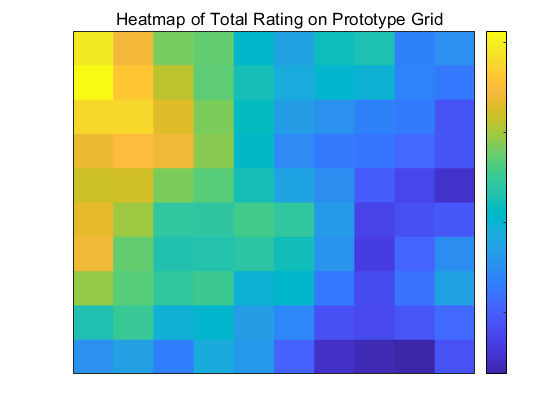


C = zeros(N,N);

for i = 1:k
    c = getCoord(i, N);
    x = c(1);
    y = c(2);
    C(x,y) = sum(M(:, i));
end

figure(30+n+1);
h = heatmap(1:N, 1:N, C, 'FontSize', 0.01, 'GridVisible',"off");
sgtitle("Heatmap of Total Rating on Prototype Grid");
h.Colormap = parula;

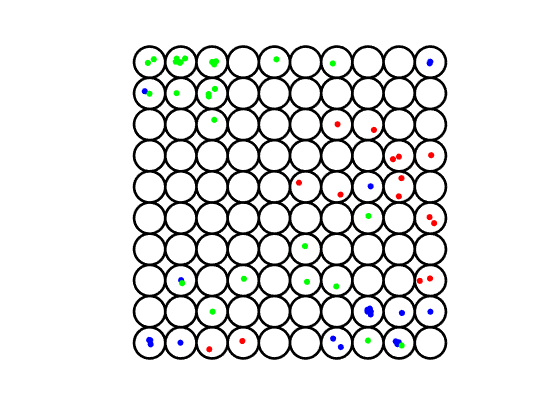

%Place the data!
figure(30)
clear figure(30)
for i = 1:p
    if(any(states(i,1:2) ~= 'CA'))
        continue
    end
    x = relativeRatings(:,i);
    [~, bmu_I] = min(vecnorm(M - x));
    c = getCoord(bmu_I, N);
    
    %Place a dot
    theta = RandRange(2*pi,0,1);
    r = RandRange(0.2,0,1);
    x_ = r*cos(theta) + c(1);
    y_ = r*sin(theta) + c(2);
    txt = states(i,:);
    %text(x_,y_,txt, 'FontSize', 10)
    scatter(x_, y_, 250, 'b.');
    hold on
end

for i = 1:p
    if(any(states(i,1:2) ~= 'PA'))
        continue
    end
    x = relativeRatings(:,i);
    [~, bmu_I] = min(vecnorm(M - x));
    c = getCoord(bmu_I, N);
    
    %Place a dot
    theta = RandRange(2*pi,0,1);
    r = RandRange(0.4,0,1);
    x_ = r*cos(theta) + c(1);
    y_ = r*sin(theta) + c(2);
    txt = states(i,:);
    %text(x_,y_,txt, 'FontSize', 10)
    scatter(x_, y_, 250, 'r.');
    hold on
end

for i = 1:p
    if(any(states(i,1:2) ~= 'TX'))
        continue
    end
    x = relativeRatings(:,i);
    [~, bmu_I] = min(vecnorm(M - x));
    c = getCoord(bmu_I, N);
    
    %Place a dot
    theta = RandRange(2*pi,0,1);
    r = RandRange(0.2,0,1);
    x_ = r*cos(theta) + c(1);
    y_ = r*sin(theta) + c(2);
    txt = states(i,:);
    %text(x_,y_,txt, 'FontSize', 10)
    scatter(x_, y_, 250, 'g.');
    hold on
end

%%SET UP CIRCLES!%%
cirlces = zeros(N,N);
q1 = [1:N]'*ones(1,N);
q2 = ones(N,1)*[1:N];
Q = [q1(:) q2(:)];
% Define the distance squared matrix
D2 = zeros(k,k);
for i = 1:k
    for j = 1:i
        D2(i,j) = norm(Q(i,:) - Q(j,:))^2;
        D2(j,i) = D2(i,j);
    end
end

% Plotting the buttons on the map
thplot = linspace(0,2*pi,k);
cc = cos(thplot);
ss = sin(thplot);
for j = 1:k
    plot(Q(j,1)*ones(1,k) + 0.5*cc,Q(j,2)*ones(1,k)+0.5*ss,'k-','LineWidth',2)
    hold on
end
axis('square')
axis([0,N+1,0,N+1])
set(gca,'FontSize',20)
set(gca, 'visible', 'off')
hold off

%%%%%